clear
clc

# 1) Carga de los datos de flores Iris obtenidos por Ronald Fisher

Estos datos están ya contenidos en Matlab, simplemente se cargan en el espacio de trabajo con la orden 'load':

load fisheriris

# 2) Examinamos los datos: ¿Tenemos razones a priori de que son conjuntos separables?

En todo trabajo de minería de datos, es importante saber como son los datos, que tipo de relaciones existen entre ellos. La mejor forma de lograr este objetivo es a través de su visualización. Es importante tener en cuenta que no siempre es posible, ya que esto dependerá del tamaño de características. Un espacio con muchas características presentará muchas dificultades a la hora de la visualización. En este caso, caso tenemos un espacio con 4 características (decirlas). Cada muestra está clasificada en "setosa", "versicolor", "virginica".


%% Explicacion estadistica de los datos
figure(1)
meas(1:10,:) % Visualizamos las 10 primeras muestras

ans =     5.1000    3.5000    1.4000    0.2000
    4.9000    3.0000    1.4000    0.2000
    4.7000    3.2000    1.3000    0.2000
    4.6000    3.1000    1.5000    0.2000
    5.0000    3.6000    1.4000    0.2000
    5.4000    3.9000    1.7000    0.4000
    4.6000    3.4000    1.4000    0.3000
    5.0000    3.4000    1.5000    0.2000
    4.4000    2.9000    1.4000    0.2000
    4.9000    3.1000    1.5000    0.1000


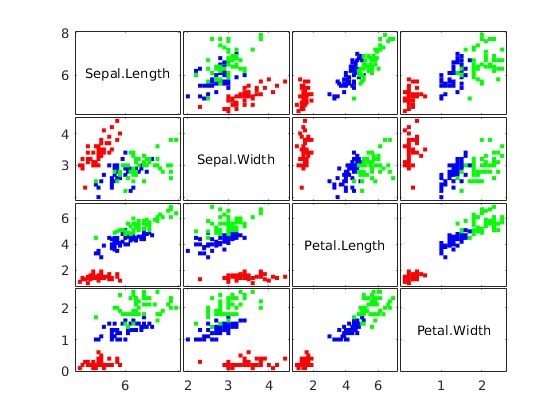


gplotmatrix(meas, [], species, ['r', 'b', 'g'],[],[],'off','variable',{'Sepal.Length','Sepal.Width','Petal.Length','Petal.Width'}); % Hacemos un plot enfrentando a todas las características

[media,std] = grpstats(meas,species,{'mean','std'})

media =     5.0060    3.4280    1.4620    0.2460
    5.9360    2.7700    4.2600    1.3260
    6.5880    2.9740    5.5520    2.0260


std =     0.3525    0.3791    0.1737    0.1054
    0.5162    0.3138    0.4699    0.1978
    0.6359    0.3225    0.5519    0.2747


¿Qué dos características eligirías para distinguir entre especies de Iris? ¿Cuál sería la peor elección?

# 3) Creacion de la red neuronal

## 3.1) En primer lugar tenemos que crear la red. 

Lo primero de todo será crear la estructura "red neuronal". Se operara como sigue:

- Seleccionar numero de capas y neuronas por capa

- Seleccionar la funcion de perdida

- Seleccionar la funcion de activación

- Seleccionar el algoritmo para backpropagation

%1
%  patternnet(hiddenSizes,trainFcn,performFcn)
neuronasPorCapaOculta = 10;
% trainFcn = 'traingd';
performFcn = 'crossentropy';
net = patternnet(neuronasPorCapaOculta,trainFcn,performFcn);
net.trainParam.lr = 0.002;

## 3.2) Division del conjunto de datos

Para poder llevar a cabo un proceso de clasificación necesitmos dividir el conjunto de datos en dos subconjuntos. El subconjunto de datos usado para el entrenamiento de la red neuronal se suele denominar "conjunto de entrenamiento",  y el subconjunto de los datos usado para realizar el test, "conjunto test".  Por otro lado, hay que tener en cuenta que el conjunto de test es un "bien muy preciado", ya que permitirá evaluar el rendimiento de tu clasificador, con lo cual no podrás utilizarlo hasta que tengas la red preparada. Esto implica, que todas las modificaciones que hagas en los parámetros de la red, no podrás probarlo en tu test, ya que sin darte cuenta estarías haciendo trampas. El motivo de esto, es que estarías usando ajustando los parámetros de tu red, a los resultados que obtienes en el test. Por este motivo se creará otro subconjunto de datos denominado "Conjunto de validación". 

## En resumen: 

- Conjunto de entrenamiento (Train Set): Con este conjunto se entrenará la red neuronal

- Conjunto de validacion (Validation Set): Con este conjunto se realizará el ajuste (tunning) de los parámetros de la red

- Conjunto de test (Test Set): Cuando ya lo tengas todos listo y creas que tu red esta ajustada para dar el mejor rendimiento posible, evaluarás su rendimiento comparándola con este conjunto.

net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;

## 3.3) Se entrena a la red

load iris_dataset.mat
[net,tr] = train(net,irisInputs,irisTargets);

## 3.4) En tercer lugar se procederá a la visualización de resultados: matrices de confunsion, curva roc, funcion de perdida.

Función de pérdida:

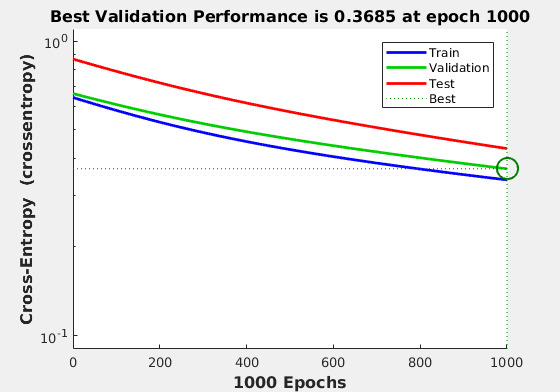

figure, plotperform(tr)

# 4) Ejercicios propuestos

%hiddenLayerSize = 10;
%trainFcn = 'trainscg' % probar con varias
my_net = network


my_net =

    Neural Network
 
              name: 'Custom Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 0
         numLayers: 0
        numOutputs: 0
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 0
        sampleTime: 1
 
    connections:
 
       biasConnect: []
      inputConnect

my_net.LW =[10 10]

Error using network/subsasgn>network_subsasgn (line 551)
net.LW must be a 0-by-0 cell array.

Error in network/subsasgn (line 10)
net = network_subsasgn(net,subscripts,v,netname);

Inspeccionamos la red que hemos creado.

my_net 


my_net =

    Neural Network
 
              name: 'Pattern Recognition Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 10
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      

La visualizamos...

view(my_net) % Visualizamos la red que hemos creado


# 4) Neural Net tuning: selección de los hiperparámetros de la red

## 4.1) Numero de neuronas y capas ocultas

Estos hiper parámetros se eligirán conjuntamente. Se creará un array, donde cada posición representará a cada capa, y el valor asociado a la posición, representará el número de neuronas, es decir: el array [7, 8 , 9] representa a una red con 3 capas ocultas y 7,8,9 neuronas en cada capa respectivamente. 

hiddenLayerSize = [10, 20, 30]; % 2 capas con 10 y 10 neuronas
my_net = patternnet(my_net, hiddenLayerSize);
my_net






Error using network/subsasgn>network_subsasgn (line 541)
Reference to non-existent field 'hiddenSizes'.

Error in network/subsasgn (line 10)
net = network_subsasgn(net,subscripts,v,netname);

Error in nnetParam/subsasgn (<a 

## 4.2) Seleccion de la función de pérdida

La función de pérdida define matemáticamente los objetivos del problema, por ello esta función es también conocida como "función objetivo". El objetivo en una problema de clasificación es encontrar los parámetros de la red (pesos y bias) que mejor separa el espacio en cuanto a clasificación. Con lo cual debemos usar una función objetivo que refleje esto. Una de las funciones objetivo más utilizada es la conocida como "cross-entropy"(https://en.wikipedia.org/wiki/Cross_entropy) . Esta función de pérdida utiliza una pseudo-distancia (https://es.wikipedia.org/wiki/Divergencia_de_Kullback-Leibler)  entre las distribuciones de probabilidad predicha y la distribución de probabilidad real, forzando a que cada vez esta divergencia sea menor, hasta alcanzar un mínimo.

lossFunction = 'crossentropy'



my_net =

    Neural Network
 
              name: 'Pattern Recognition Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 10
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      